# ICEL9 Data Analysis Workshop

MATLAB version - J.I.M. Parmentier, collaboration with Christoffer Roepstorff

Utrecht University - August 2023

## Skeleton of the assignment - part 3 (comparing timepoints, T0, T1 and T3 of one pony)

In this part of the assignment, we simply repeat the steps of part 1 and loop them for the three timepoints for one pony. Then, we plot the results to see how the asymmetry parameters of the pony changed over time.

## I. Load the data and declare the variables of interest

To load the data, you need to first define a datapath. You can copy-paste below where your data is located:

clear all; close all; clc;

results = table(NaN,NaN,NaN,NaN,NaN,NaN,NaN,{''},{''});
results.Properties.VariableNames  = {'StrideDuration',...
        'MinDiff_Head','MaxDiff_Head',...
        'MinDiff_Withers','MaxDiff_Withers',...
        'MinDiff_Pelvis','MaxDiff_Pelvis',...
        'HorseID','TimePoint'};

datapath = 'C:\Users\ParmentierJIM\OneDrive - Universiteit Utrecht\ICEL9-DataAnalysis-Workshop\PonyKinematics\data';

In this section, we will work with the data of horse A at timepoint T0 only. You can define this in the following HorsesList variable:

HorsesList = {'horseA'};
TimePointsList = {'T0','T1','T2'};

We will work with three upper-body markers: Head ('Poll'), Withers ('T8') and the Pelvis ('TubSac'). You can define them below:

MarkersUpperBody = {'Poll','T8','TubSac'};
MarkersNames = {'Head','Withers','Pelvis'};

For splitting the data into strides for the analysis, we will use the left hind hoof ('Hoof_LH') only.

MarkersStrideSplit = {'Hoof_LH'};

You can now look for your data file and load it!

files = [];
for i_horse = 1:length(HorsesList)
    for i_tp = 1:length(TimePointsList)
        filesTemp = dir(strcat(datapath,'/',TimePointsList{i_tp},'_',...
            HorsesList{i_horse},'_trot1.mat'));
        files = [files;filesTemp];
    end
end

if ~isempty(files)
    uiwait(msgbox('Congratulations! You found a file. We are downloading it for you.'));
else
    errordlg('We could not find a file. Please check your datapath, horse name and time point name.',...
        'File Error');
end

We have found all the files. Now, within a loop, we are going to process them one by one and extract all the data! 

## II. Loop through the files

To help with the missing samples, we have already manually defined which segments to use. You can read the csv file with the information.

segmentTimestamps = readtable('.\data\timestamps.xlsx');

for i_file = 1:length(files)
    Data = load([files(i_file).folder,'/',files(i_file).name]);
    temp = fieldnames(Data);
    Data = Data.(temp{1});
    HorseID = extractBefore(files(i_file).name,'_trot1');
    HorseID = extractAfter(HorseID,'_horse');
    TimePoint = extractBefore(files(i_file).name,'_horse');

    ind = find(strcmp(segmentTimestamps.Pony, HorseID)==1 & strcmp(segmentTimestamps.Timepoint,TimePoint)==1);
    
    segment_start = segmentTimestamps.start(ind); 
    segment_stop = segmentTimestamps.stop(ind); ind = [];

    %% Extract the trajectories
    Trajectories = permute(Data.Trajectories.Labeled.Data,[3, 2, 1]); % 3D displacements data

    MarkersName = Data.Trajectories.Labeled.Labels; % Markers names
    Fs = Data.FrameRate; % Sampling frequency, in Hz
    Time = 0:1/Fs:(Data.Frames-1)/Fs; % Creating a Time vector

    ind_head = find(strcmp(MarkersName , MarkersUpperBody{1})==1); % Poll
    ind_withers = find(strcmp(MarkersName , MarkersUpperBody{2})==1); % T8 (Withers)
    ind_pelvis = find(strcmp(MarkersName , MarkersUpperBody{3})==1); % Tubera Sacrale (Pelvis)

    ind_LHhoof = find(strcmp(MarkersName , MarkersStrideSplit{1})==1); % LH Hoof

    Head_data = Trajectories(:,:,ind_head); % Poll
    Withers_data = Trajectories(:,:,ind_withers); % T8
    Pelvis_data = Trajectories(:,:,ind_pelvis); % Tubera Sacrale
    LHHoof_data = Trajectories(:,:,ind_LHhoof); % LH hoof
  
    %% Extract the defined segment
    [~,beginning_ind] = min(abs(Time-segment_start));
    [~,end_ind] = min(abs(Time-segment_stop));

    Extracted_Time = Time(beginning_ind:end_ind);
    Extracted_Head_data = Head_data(beginning_ind:end_ind,:);
    Extracted_Withers_data = Withers_data(beginning_ind:end_ind,:);
    Extracted_Pelvis_data = Pelvis_data(beginning_ind:end_ind,:);
    Extracted_LHHoof_data = LHHoof_data(beginning_ind:end_ind,:);
 
    % Plot
    figure
    ax(1) = subplot(211);
    plot(Extracted_Time,Extracted_Head_data(:,3)- mean(Extracted_Head_data(:,3),'omitnan')); hold on
    plot(Extracted_Time,Extracted_Withers_data(:,3)-mean(Extracted_Withers_data(:,3),'omitnan'));
    plot(Extracted_Time,Extracted_Pelvis_data(:,3)-mean(Extracted_Pelvis_data(:,3),'omitnan'));
    legend('Head','Withers','Pelvis');
    xlabel('Time (s)');
    ylabel('Vertical displacement (mm)');

    ax(2) = subplot(212);
    plot(Extracted_Time,Extracted_LHHoof_data(:,3)- mean(Extracted_LHHoof_data(:,3),'omitnan')); hold on
    legend('LH hoof');
    xlabel('Time (s)');
    ylabel('Vertical displacement (mm)');


    linkaxes(ax,'x');

Below, we first verify is there are missing samples in the marker vertical displacement. If the consecutive missing data is below 20 samples, we fill it with the function "fillMissingMarkerData". If you want to see the results of this function, change "PlotMissingData" to 1.

    maxGapMissingData = 20;
    PlotMissingData = 0;

    toFilter_head = Extracted_Head_data(:,3)-mean(Extracted_Head_data(:,3),'omitnan');
    toFilter_withers = Extracted_Withers_data(:,3)-mean(Extracted_Withers_data(:,3),'omitnan');
    toFilter_pelvis = Extracted_Pelvis_data(:,3)-mean(Extracted_Pelvis_data(:,3),'omitnan');
    
    toFilter_head = fillMissingMarkerData(toFilter_head,maxGapMissingData,PlotMissingData);
    toFilter_withers = fillMissingMarkerData(toFilter_withers,maxGapMissingData,PlotMissingData);
    toFilter_pelvis = fillMissingMarkerData(toFilter_pelvis,maxGapMissingData,PlotMissingData);

Then, we detrend the data before applying a bandpass filter.

    toFilter_head = detrend(toFilter_head);
    toFilter_withers = detrend(toFilter_withers);
    toFilter_pelvis = detrend(toFilter_pelvis);

    Fc_lp =0.5;  Fc_hp =7;
    [b,a] = butter(4,[Fc_lp/(Fs/2),Fc_hp/(Fs/2)],'bandpass');

    filtered_data_head = filtfilt(b,a,toFilter_head);
    filtered_data_withers = filtfilt(b,a,toFilter_withers);
    filtered_data_pelvis = filtfilt(b,a,toFilter_pelvis);

We apply the same fillMissingMarkerData function to the hoof marker, before splitting the data into strides, based on LH hoof on events.

    %% Stride split
    LHHoof_z = Extracted_LHHoof_data(:,3);

    % Find NaN in the data
    LHHoof_z = fillMissingMarkerData(LHHoof_z,maxGapMissingData,PlotMissingData);

    % Find change points, keep only the ones for hoof on
    LHHoof_z_temp = LHHoof_z;
    if min(LHHoof_z) < 0 
        threshold_HO = 5;
        LHHoof_z_temp(LHHoof_z > threshold_HO) = threshold_HO;
    else
        LHHoof_z_temp = LHHoof_z - (min(LHHoof_z)*4);
        LHHoof_z_temp(LHHoof_z_temp > 0) = (min(LHHoof_z)*4);
        threshold_HO = (min(LHHoof_z)*4);
    end
 
    [~,~,changeIndices] = zerocrossrate(LHHoof_z_temp);
    changeIndices = find(changeIndices==1);

    if length(LHHoof_z) < changeIndices(end)+5
        changeIndices(end) = [];
    end
    if changeIndices(1) == 1
        changeIndices(1) = [];
    end
    for i = length(changeIndices):-1:1
        if LHHoof_z_temp(changeIndices(i)-3) < threshold_HO %% Means that previous samples are stance, thus this is a Hoof Off
            changeIndices(i) = [];
        end
    end
    figure
    plot(LHHoof_z); hold on
    plot(LHHoof_z_temp);
    xline(changeIndices,'r')

    strides = cell(length(changeIndices)-1,3);
    figure
    % Push it a bit more to the right to be sure to have the right peaks
    for i = 1:length(changeIndices)-1
        strides{i,1} = filtered_data_head(changeIndices(i):changeIndices(i+1)+5); 
        strides{i,2} = filtered_data_withers(changeIndices(i):changeIndices(i+1)+5);
        strides{i,3} = filtered_data_pelvis(changeIndices(i):changeIndices(i+1)+5);

        for k = 1:3
            subplot(2,3,k)
            plot(strides{i,k}); hold on;
        end
    end
    subplot(231)
    title('Extracted strides, head'); xlabel('Samples');ylabel('Vert. disp (mm)')
    subplot(232)
    title('Extracted strides, withers');xlabel('Samples');ylabel('Vert. disp (mm)')
    subplot(233)
    title('Extracted strides, pelvis');xlabel('Samples');ylabel('Vert. disp (mm)')
    sgtitle(strcat('Horse: ',HorseID,', Timepoint: ',TimePointsList{1}));



Finally, we extract for each strides the Head, Withers and Pelvis MinDiff and MaxDiff, as well as the stride duration.

    for i = 1:size(strides,1)
%         figure
        for k =1:3
            [pks,~] = findpeaks(strides{i,k});
            [~,ind] = findpeaks(-strides{i,k});

Sometimes, only one peak is found (e.g. very lame horse, or issues is the stride events detection). If more than 2 peaks are found, this is also due to an issue in the stride split or wobbling markers/sensors.

Another way to get around this problem is to do a Fast-Fourier transformation (FFT). 

            if length(pks) < 2 % Missing peak
                pks(1) = NaN; pks(2) = NaN;
            elseif length(pks) == 3 % One peak too many
                pks(1) = [];
            end

            if length(ind) == 3 % One peak too many
                ind(1) = [];
            end

            if k == 1 || 2
                MaxDiff(i,k) = pks(2) - pks(1);
                if length(ind) < 2
                    MinDiff(i,k) = NaN; 
                else
                    MinDiff(i,k) = strides{i,k}(ind(2)) - strides{i,k}(ind(1));
                end
                
            else
                MaxDiff(i,k) = pks(1) - pks(2);
                if length(ind) < 2
                    MinDiff(i,k) = NaN; 
                else
                    MinDiff(i,k) = strides{i,k}(ind(1)) - strides{i,k}(ind(2));
                end
            end
        end
        StrideDuration(i) = Extracted_Time(changeIndices(i+1))-Extracted_Time(changeIndices(i));

%         for ii = 1:length(pks)
%             ind_temp(ii) = find(strides{i,k}==pks(ii));
%         end
%         plot(strides{i,k}); hold on
%         plot(ind_temp,pks,'vr');
%         plot(ind,strides{i,k}(ind),'^b'); pause; close; ind_temp = [];
    end

    for k = 1:3
        subplot(2,3,3+k)
        tplot = [MaxDiff(:,k),MinDiff(:,k)];
        cgr = [repmat({'MaxDiff'},1,length(MaxDiff(:,k))),...
            repmat({'Mindiff'},1,length(MinDiff(:,k)))];
        boxplot(tplot,cgr);
        ylim([-40 40]); yline(0,'r');
        title(MarkersNames{k}); ylabel('Asymmetry index (mm)'); grid on
    end



Below, we save the results in a results table variable. At the end of the loop, we will export this table outside of MATLAB. The results can be used to plot and in statistical analysis.

    temp = [StrideDuration',MinDiff(:,1),MaxDiff(:,1),...
                            MinDiff(:,2),MaxDiff(:,2),...
                            MinDiff(:,3),MaxDiff(:,3)];
    tempInfo = repmat([{HorseID},{TimePoint}],length(MinDiff),1);
    temptable1 = array2table(temp);
    temptable2 = cell2table(tempInfo);

    temptable = [temptable1,temptable2];
    temptable.Properties.VariableNames  = {'StrideDuration',...
        'MinDiff_Head','MaxDiff_Head',...
        'MinDiff_Withers','MaxDiff_Withers',...
        'MinDiff_Pelvis','MaxDiff_Pelvis',...
        'HorseID','TimePoint'};

    results = [results;temptable];

    clearvars -except results HorsesList TimePointsList files datapath segmentTimestamps MarkersUpperBody...
        MarkersStrideSplit MarkersNames;
    close all; clc;
end
results(1,:) = [];

Now, we are going to plot each variable's mean and standard deviation for each time point:

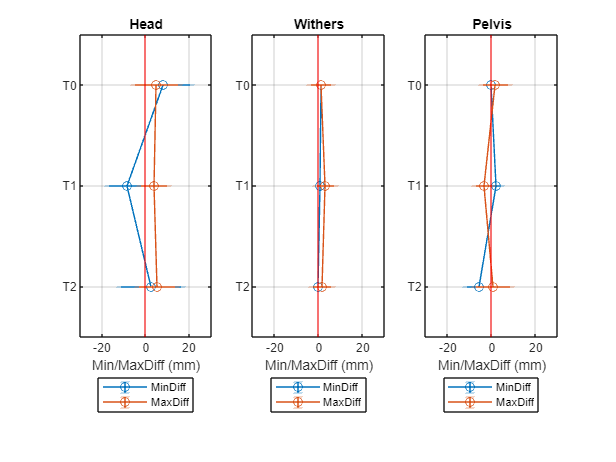

results_byHorseTimePoint = groupsummary(results,["HorseID","TimePoint"],...
    {"mean","std"},["MinDiff_Head","MaxDiff_Head",...
    "MinDiff_Withers","MaxDiff_Withers",...
    "MinDiff_Pelvis","MaxDiff_Pelvis",...
    "StrideDuration"]);
x = [1 2 3];

close all
figure
ax(1) = subplot(131);
y = results_byHorseTimePoint.mean_MinDiff_Head;
err = results_byHorseTimePoint.std_MinDiff_Head;
errorbar(x,y,err,'o-'); hold on
y = results_byHorseTimePoint.mean_MaxDiff_Head;
err = results_byHorseTimePoint.std_MaxDiff_Head;
errorbar(x,y,err,'o-'); 

yline(0,'r','HandleVisibility','off');
xlim([0.5 3.5]);
xticks([1 2 3]);
xticklabels({'T0','T1','T2'});
ylim([-30 30]); grid on; title('Head'); 
legend('MinDiff','MaxDiff','Orientation','vertical',...
    'Location','southoutside')
set(ax(1),'YAxisLocation','right'); ylabel('Min/MaxDiff (mm)');
camroll(-90)

ax(2) = subplot(132);
y = results_byHorseTimePoint.mean_MinDiff_Withers;
err = results_byHorseTimePoint.mean_MinDiff_Withers;
errorbar(x,y,err,'o-'); hold on
y = results_byHorseTimePoint.mean_MaxDiff_Withers;
err = results_byHorseTimePoint.std_MaxDiff_Withers;
errorbar(x,y,err,'o-'); 

yline(0,'r','HandleVisibility','off');
xlim([0.5 3.5]);
xticks([1 2 3]);
xticklabels({'T0','T1','T2'});
ylim([-30 30]); grid on; title('Withers'); 
legend('MinDiff','MaxDiff','Orientation','vertical',...
    'Location','southoutside')
set(ax(2),'YAxisLocation','right'); ylabel('Min/MaxDiff (mm)');
camroll(-90);


ax(3) = subplot(133);
y = results_byHorseTimePoint.mean_MinDiff_Pelvis;
err = results_byHorseTimePoint.mean_MinDiff_Pelvis;
errorbar(x,y,err,'o-'); hold on
y = results_byHorseTimePoint.mean_MaxDiff_Pelvis;
err = results_byHorseTimePoint.std_MaxDiff_Pelvis;
errorbar(x,y,err,'o-'); 

yline(0,'r','HandleVisibility','off');
xlim([0.5 3.5]);
xticks([1 2 3]);
xticklabels({'T0','T1','T2'});
ylim([-30 30]); grid on; title('Pelvis'); 
legend('MinDiff','MaxDiff','Orientation','vertical',...
    'Location','southoutside')
set(ax(3),'YAxisLocation','right'); ylabel('Min/MaxDiff (mm)');
camroll(-90); set(gcf,'Color','white')